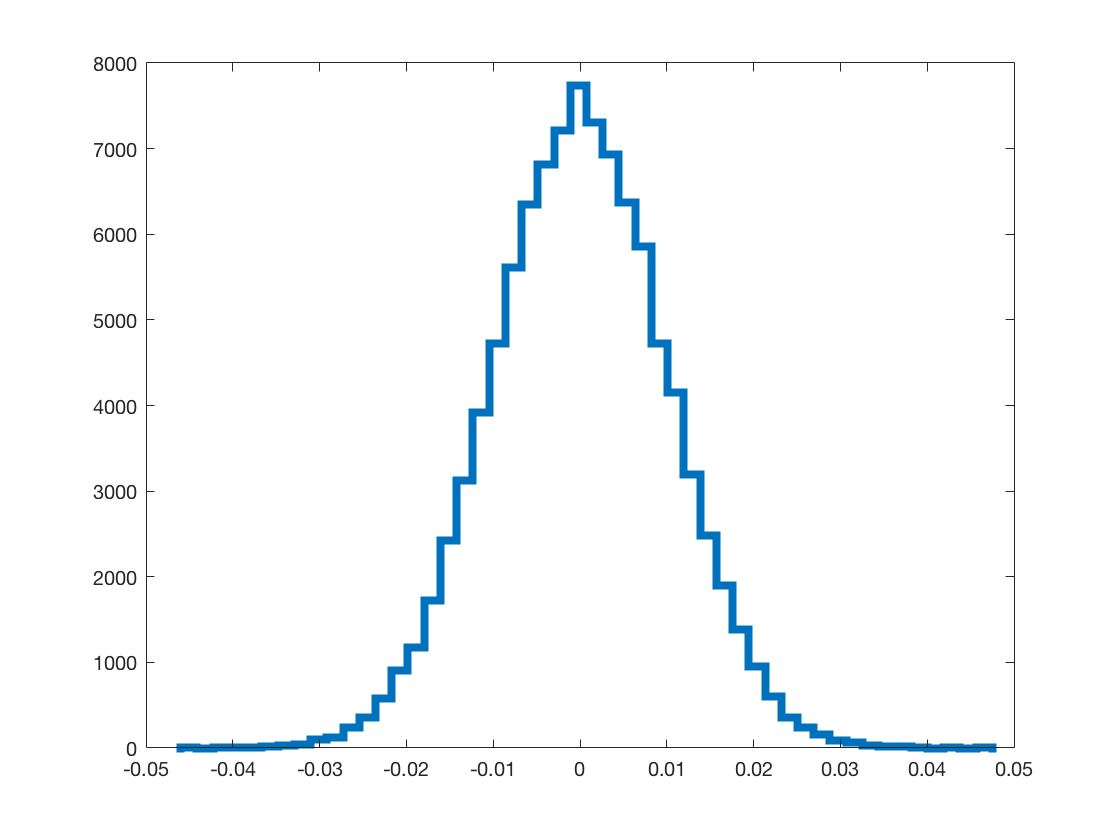

% PHYS 434
% LAB 1
% Jin Kyoung Lee


% 1: Converting a probability into a 'sigma'.
% creating random distribution
d = random('Normal', 0, 0.01, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',4) % creating histogram of distribution
xlim([-0.05,0.05]) % limiting the range of x showing on the graph


histogram(d,50,'DisplayStyle',"stairs", 'LineWidth',3,"Normalization","pdf")
hold on
x1 = linspace(-0.05,0.05,1000) % generating vector x of 1000 points linearly spaced b/w -.05 and .05

x1 =    -0.0500   -0.0499   -0.0498   -0.0497   -0.0496   -0.0495   -0.0494   -0.0493   -0.0492   -0.0491   -0.0490   -0.0489   -0.0488   -0.0487   -0.0486   -0.0485   -0.0484   -0.0483   -0.0482   -0.0481   -0.0480   -0.0479   -0.0478   -0.0477   -0.0476   -0.0475   -0.0474   -0.0473   -0.0472   -0.0471   -0.0470   -0.0469   -0.0468   -0.0467   -0.0466   -0.0465   -0.0464   -0.0463   -0.0462   -0.0461   -0.0460   -0.0459   -0.0458   -0.0457   -0.0456   -0.0455   -0.0454   -0.0453   -0.0452   -0.0451


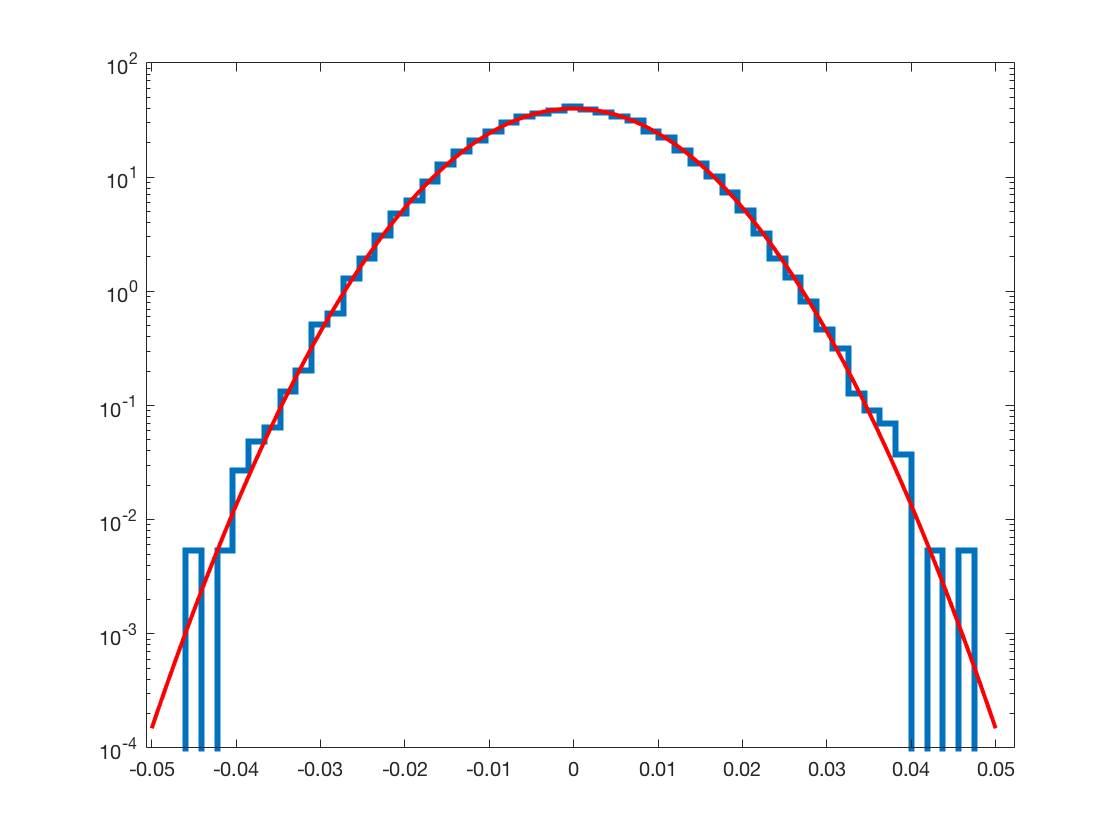

% creating normal(Gaussian) distribution
pd = makedist("Normal",'mu',0,'sigma',0.01);
plot(x1,pdf(pd,x1),"Red","LineWidth",2);
set(gca,'YScale','log')
hold off


% integrating the stardard normal distribution
p = normcdf(x1,0,0.01)

p =     0.0287    0.0302    0.0318    0.0335    0.0353    0.0371    0.0391    0.0411    0.0433    0.0456    0.0479    0.0504    0.0531    0.0558    0.0587    0.0618    0.0650    0.0683    0.0718    0.0755    0.0794    0.0835    0.0877    0.0922    0.0969    0.1018    0.1070    0.1124    0.1181    0.1240    0.1303    0.1368    0.1437    0.1508    0.1584    0.1662    0.1745    0.1832    0.1922    0.2017    0.2117    0.2221    0.2330    0.2444    0.2563    0.2688    0.2819    0.2956    0.3099    0.3249



% determining the associated 'sigma' value for a given probability
% trying some probability values
percent = [.8413,.9773] % 1 sigma = 84.13%, 2 sigma = 97.73%

percent =     0.8413    0.9773


sigmaTrial = norminv(percent)

sigmaTrial =     0.9998    2.0009


% converting probability into sigma
sigma = norminv(p)

sigma =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9499   -4.9399   -4.9299   -4.9199   -4.9099   -4.8999   -4.8899   -4.8799   -4.8699   -4.8599   -4.8498   -4.8398   -4.8298   -4.8198   -4.8098   -4.7998   -4.7898   -4.7798   -4.7698   -4.7598   -4.7497   -4.7397   -4.7297   -4.7197   -4.7097   -4.6997   -4.6897   -4.6797   -4.6697   -4.6597   -4.6496   -4.6396   -4.6296   -4.6196   -4.6096   -4.5996   -4.5896   -4.5796   -4.5696   -4.5596   -4.5495   -4.5395   -4.5295   -4.5195   -4.5095


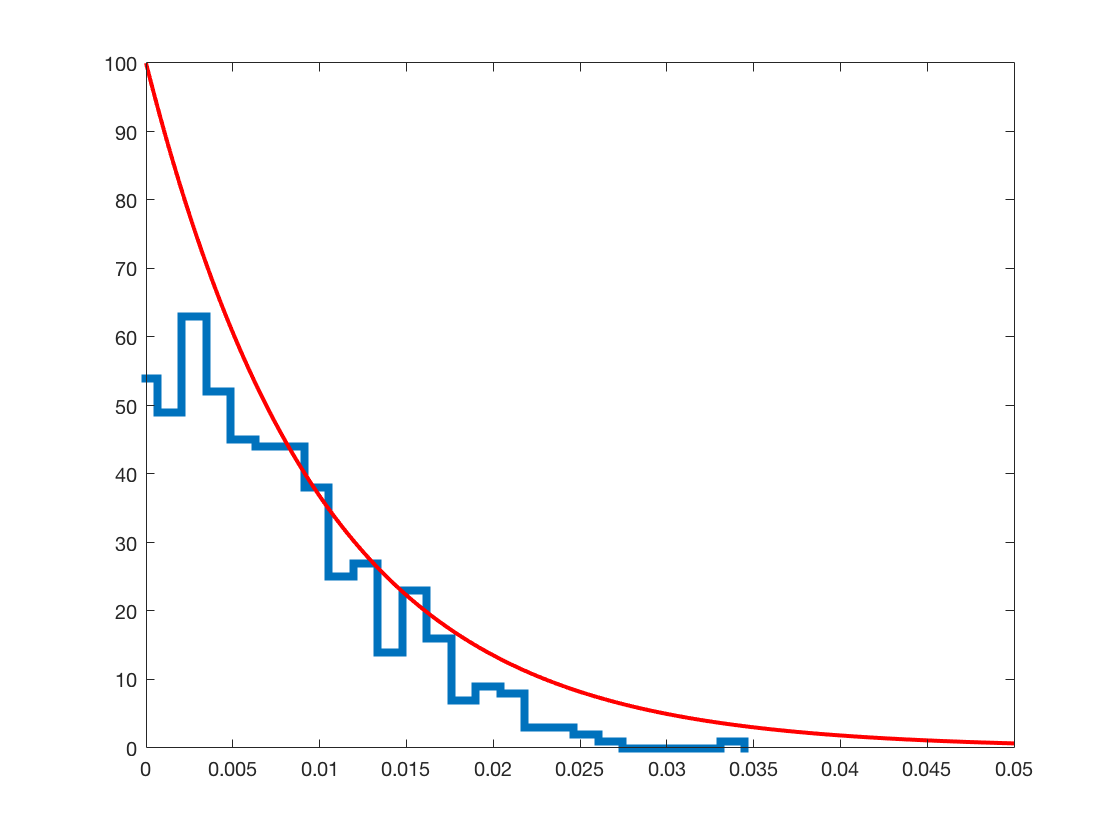


% D. The minus sign that appears means that ...?


% 2: Continuous analytic distribution: Exponential
% making plot of exponential distribution
d2 = random('Normal', 0, 0.01, [1,1000]);
histogram(d2,50,'DisplayStyle',"stairs",'LineWidth',4) % creating histogram of distribution
xlim([0,0.05]) % limiting the range of x showing on the graph
hold on
x2 = linspace(0,0.05,1000);
expd = makedist("Exponential","mu",.01);
plot(x2,pdf(expd,x2),"Red","LineWidth",2);